 **Practical Problems 2 – Plotting & Programming** 	

1.Plot the exponential function between *x* = -10 and 10 using a red dashed line, then plot the points at each integer value of *x* in large green crosses. Remember to add axes labels and a figure title.

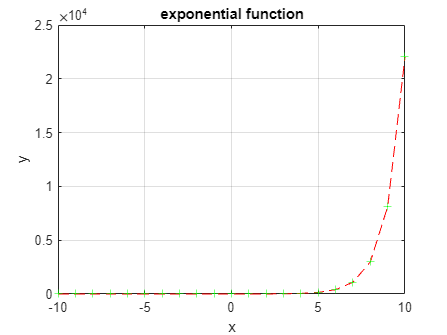

x_expo = -10:10;
y_expo = exp(x_expo);
plot(x_expo, y_expo, 'r--')
hold on;
plot(x_expo, y_expo, 'g+')
xlabel('x')
ylabel('y')
title('exponential function')
grid on;
hold off;

2.Use 2 subplots above and below each other to plot both sin(*x*) and cos(*x*) between -2π and 2π. Customise the plots any way you like.

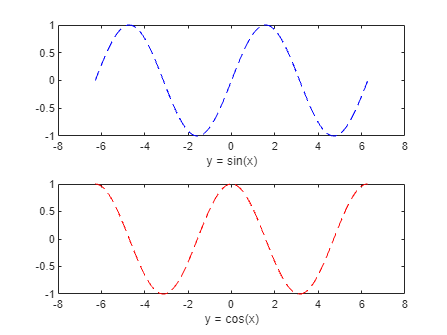

x = (-2*pi):0.01:(2*pi);
y1 = sin(x);
y2 = cos(x);
subplot(2, 1, 1);
plot(x, y1, 'b--')
xlabel('y = sin(x)')
hold off;

subplot(2, 1, 2);
plot(x, y2, 'r--')
xlabel('y = cos(x)')
hold off;

3.Plot the following data in a pie chart and explode the Honda and Mercedes segments.

**Car Manufacturer                    Number of Sales**

BMW                                                   37,210

Honda                                                412,178

Isuzu                                                  366,040

Mercedes                                             53,442

Mitsubishi                                           157,803

Nissan                                                210,000

Toyota                                                845,213

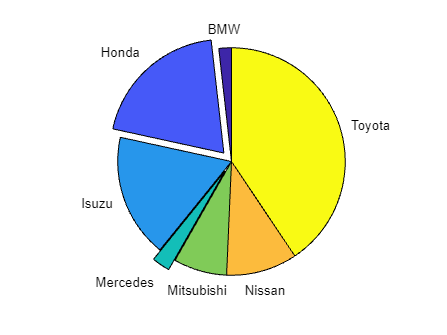

car = {'BMW', 'Honda', 'Isuzu', 'Mercedes', 'Mitsubishi', 'Nissan', 'Toyota'};
sales = [37210, 412178, 366040, 53442, 157803, 210000, 845213];
explode = [0, 1, 0, 1, 0, 0, 0];
figure;
pie(sales, explode, car)

4.Plot


$$\frac{1}{{\left(x-1\right)}^2 }$$
        

between -10 and 10, but only display the *y*-axis between 0 and 1.

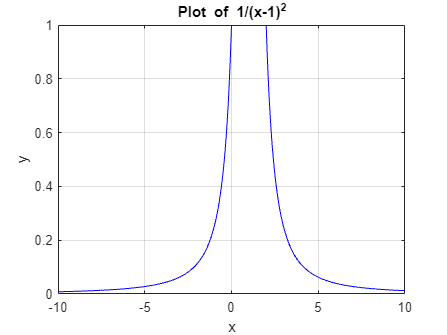

x = -10:0.01:10;
y = 1./(x-1).^2;
figure;
plot(x, y, 'b')
ylim([0, 1]);
xlabel('x');
ylabel('y');
title('Plot of 1/(x-1)^2');
grid on;

5.Create a character array called ***x*** that contains the first 6 letters of the alphabet. The vector should contain 6 separate character elements.

x = ['a', 'b', 'c', 'd', 'e', 'f']

x = 'abcdef'

6.Display every odd element in the command window with a 2 second pause in between.

for i = 1:2:length(x)
    disp(x(i));
    pause(2);
end

a
c
e


7.Create a 3 `x` 3 string matrix called ***A*** containing the first 9 letters of the alphabet.

A = ['a', 'b', 'c';'d', 'e', 'f';'g', 'h', 'i']

A = 3×3 char array
    'abc'
    'def'
    'ghi'


8.Print the diagonal entries of ***A*** with a 3 second pause in between.

for i = 1:3
    disp(A(i, i));
    pause(3);
end

a
e


9.Create a 1 `x` 8 vector of random integers called *y*.

y = randi([1, 100], 1, 8)

y =     75    40    66    18    71     4    28     5


10.Write a for loop that replaces elements of *y* that have an even value with 0 and elements that have an odd value with 1.

disp(y)

    75    40    66    18    71     4    28     5



for i = 1:length(y)
    if mod(y(i), 2) ==0
        y(i) = 0
    else
        y(i) = 1
    end
end

y =      1    40    66    18    71     4    28     5


y =      1     0    66    18    71     4    28     5


y =      1     0     0    18    71     4    28     5


y =      1     0     0     0    71     4    28     5


y =      1     0     0     0     1     4    28     5


y =      1     0     0     0     1     0    28     5


y =      1     0     0     0     1     0     0     5


y =      1     0     0     0     1     0     0     1


11.Create a 6 `x` 1 vector of random integers between 20 and 50 called *z*.

z = randi([20, 50], 6, 1)

z =     40
    21
    46
    48
    41
    43


12.Write a for loop that subtracts 12 from an element of *z* that has a value between 27 and 43.

for i = 1:length(z)
    if z(i) >= 27 && z(i) <= 43
        z(i) = z(i) - 12;
    end
end
disp(z)

    28
    21
    46
    48
    29
    31



13.Write a for loop that doubles the 2nd, 4th and 5th entries of *y*.

for i = 1:length(y);
    if i ==2 || i==4 || i==5
        y(i) = y(i) * 2;
    end
end
disp(y)

     1     0     0     0     2     0     0     1



14.Repeat the task in question 13 **without using a loop** (just vector notation).

y([2, 4, 5]) = y([2, 4, 5])*2;
y

y =      1     0     0     0     4     0     0     1


15.Write a while loop that multiplies a number by 2 until the answer is greater than 100. Test your code with numbers of your choice.

num = input('Enter your number: ');
while num <= 100
    num = num *2;
    disp(num);
end

    10

    20

    40

    80

   160



16.Write a while loop that decreases a number by 10 until it is less than 0.

num = input('Enter your number: ');
while num >= 0
    num = num - 10;
    disp(num);
end

    90

    80

    70

    60

    50

    40

    30

    20

    10

     0

   -10



17.Write a function that accepts a number as an argument. Check if it is positive or negative. If it is positive then double it, if it is negative then halve it. Return the value. Remember to give your function a descriptive name.

result_num = check_number(input('Enter your number: '));
disp(result_num);

   200



18.Write a function that accepts a number as an argument. Check if it is even or odd. If it is even, add 1 to it. If it is odd, subtract 1 from it. Return the value.

result_EvenOdd = check_EvenOdd(input('Enter your number: '));
disp(result_EvenOdd);

    98



19.Write a function that accepts 2 numbers as arguments. Check if they are equal to each other. If they are, then add them. If they are not, then return the absolute value of their difference.

result_DiffOrSum = check_DiffOrSum();
disp(result_DiffOrSum);

     6



20.Write a function that accepts 2 numbers as arguments. If their sum is not equal to 10 then return false. If it is equal to 10, return true.

result_SumEqualsTen = checkSumEqualsTen();
disp(result_SumEqualsTen);

   0



21.Write a function that accepts 3 numbers as arguments. Add the largest 2 numbers together. Return the result.

result_SumEqualsTen = sumOfLargestTwo();
disp(result_SumEqualsTen);

    11



22.Write a function that accepts 3 numbers as arguments. Subtract the smallest number from the largest. Return the result.

result_diffBetweenLargestAndSmallest = diffBetweenLargestAndSmallest()

result_diffBetweenLargestAndSmallest = 2

disp(result_diffBetweenLargestAndSmallest);

     2



23.Write a function that accepts a vector as an input argument. The function should print the number of elements of the input vector as well as its smallest 2 values. If the vector has less than 2 elements the function should tell the user it requires more inputs.

printVectorInfo()

     2

     3

Smallest number : 2
Second Smallest number : 3


24.Write a script that creates a random vector of 1’s and 0’s then finds the indexes of the non-zero elements (read about the find function).

rand_vector = randi([0, 1], 1, 10);
% disp(rand_vector)
non_zero = find(rand_vector)

non_zero =      3     5     7     9    10


25.Write a script which creates a random 4 `x` 4 matrix of integers, then finds the even numbers and sets them equal to 0. The final matrix should be only odd numbers and 0 values.

rand_matrix = randi([0, 100], 4, 4);
disp(rand_matrix)

     8    93    23    52
    26    73    46    23
    80    49    97    49
     2    58    55    63



for j = 1 : length(rand_matrix)
    % disp(j)
    for k = 1 : length(rand_matrix)
        % disp(k)
        if mod(rand_matrix(j ,k), 2) == 0
            rand_matrix(j ,k) = 0;

        end
    end
end
disp(rand_matrix)

     0    93    23     0
     0    73     0    23
     0    49    97    49
     0     0    55    63



26.Convert the script into a function which accepts a value, *n*, as an input argument to make an *n *`x`* n* matrix. Set the even numbers equal to 0.

n = input('Put the number of matrix : ');
evenNumberToZero(n);

    26    13    66
    33    72    49
    68    10    78

     0    13     0
    33     0    49
     0     0     0



27.Make a new function which takes two input arguments, *n* and *m*, which define an *n* `x` *m* matrix. Set the odd numbers equal to 0.

n = input('Put the n number of matrix : ');
m = input('Put the m number of matrix : ');

oddNumberToZero(n, m);

    50    68    52    82
    47     4     9    72
     6     7    82    15

    50    68    52    82
     0     4     0    72
     6     0    82     0



28.Create a function which takes a value, *x*, and matrix, ***A***, as inputs. It will set any entries of the input matrix greater than *x* equal to 0 and return the result.

x = input('Put the x number of matrix : ');
A = input('Put the  matrix : ');

filterMatrix(x, A);

     1     2     3     4
     5     6     7     8

     1     2     3     4
     0     0     0     0



29.The following series converges to 1. Write a function that accepts a number specifying a tolerance, *tol*, as input argument. Calculate the sum of the series, until the answer is within *tol* away from 1. Display how many terms are required for the given precision.                                                    


$$S=\sum_{i=1}^n \frac{1}{2^i }$$


tol = input('put you tol : ');
seriesConvergence(tol);

sum = 0.5000

n = 2

sum = 0.7500

n = 3

sum = 0.8750

n = 4

sum = 0.9375

n = 5

sum = 0.9688

n = 6

sum = 0.9844

n = 7

Number of terms required for precision within 0.030000 of 1: 7


30.Write a function which accepts a number, *n*, as input argument. Calculate Euler’s number up to and including *n *terms *using *the following recursive formula.                                                   


$$e=\sum_{i=0}^n \frac{1}{i!}$$


n = input('put you n : ');
calculateEulerNumber(n)

the approximation of Euler number when n = 0 is 1.000000
the approximation of Euler number when n = 1 is 2.000000
the approximation of Euler number when n = 2 is 2.500000
the approximation of Euler number when n = 3 is 2.666667


ans = 2.6667

**Challenge Problem**The golden spiral can be approximated using the Fibonacci sequence:                                               

1, 1, 2, 3, 5, 8, 13, 21, 34…

where each number is the sum of the previous 2 numbers.Recreate the Fibonacci spiral shown on the next page by plotting squares as shown with lengths equal to the numbers in the Fibonacci sequence, and then adding quarter circular arcs, which join opposite corners of each square, to the plot. The file should be a function or script that specifies the number of terms in the Fibonacci sequence and produces the corresponding plot.**Hint:** You will probably need to use pen and paper to figure out the coordinates of each of the squares. Also to plot a square you must use 5 points. The first and last coordinate points must be the same!

function result = check_number(number)
    if number > 0
        result = number * 2;
    elseif number < 0
        result = number / 2;
    else
        result = 0;
    end
end

function result = check_EvenOdd(number)
if mod(number, 2) == 0
    result = number + 1;
elseif mod(number, 2) == 1
    result = number - 1;
end
end

function result = check_DiffOrSum()
a = input('Enter the first number: ');
b = input('Enter the second number: ');
if a == b
    result = a + b;
else
    result = abs(a - b);
end
end

function result = checkSumEqualsTen()
    a = input('Enter the first number: ');
    b = input('Enter the second number: ');
    
    result = (a + b) == 10;
end

function result = sumOfLargestTwo()
    a = input('Enter the first number: ');
    b = input('Enter the second number: ');
    c = input('Enter the third number: ');
    
    sorted_values = sort([a, b, c], 'descend');
    result = sorted_values(1) + sorted_values(2);
end

function result = diffBetweenLargestAndSmallest()
    a = input('Enter the first number: ');
    b = input('Enter the second number: ');
    c = input('Enter the third number: ');

    sorted_values = sort([a, b, c], 'ascend');
    result = sorted_values(3) - sorted_values(1);
end

function printVectorInfo()
    while 1
        vector = input('Enter a vector: ');
        
        if length(vector) < 2
            disp('Requires more inputs.');
    
        else
            break

        end
    end
    sorted_vector = sort(vector);
    % disp(sorted_vector(1))
    % disp(sorted_vector(2))
    disp(['Smallest number : ' num2str(sorted_vector(1))]);
    disp(['Second Smallest number : ' num2str(sorted_vector(2))]);

end

function evenNumberToZero(n)
n_rand_matrix = randi([0, 100], n, n);
disp(n_rand_matrix)
for j = 1 : length(n_rand_matrix)
    % disp(j)
    for k = 1 : length(n_rand_matrix)
        % disp(k)
        if mod(n_rand_matrix(j ,k), 2) == 0
            n_rand_matrix(j ,k) = 0;

        end
    end
end
disp(n_rand_matrix)
end

function oddNumberToZero(n, m)
nm_rand_matrix = randi([0, 100], n, m);
disp(nm_rand_matrix)
for j = 1 : size(nm_rand_matrix, 1)
    % disp(j)
    for k = 1 : size(nm_rand_matrix, 2)
        % disp(k)
        if mod(nm_rand_matrix(j ,k), 2) == 1
            nm_rand_matrix(j ,k) = 0;

        end
    end
end
disp(nm_rand_matrix)
end

function filterMatrix(x, A)
disp(A)
for j = 1 : size(A, 1)
    % disp(j)
    for k = 1 : size(A, 2)
        % disp(k)
        if A(j ,k) > x
            A(j ,k) = 0;

        end
    end
end
disp(A)
end

function n = seriesConvergence(tol)
    n = 1;
    sum = 0;

    while abs(sum - 1) > tol
        sum = sum + ( 1 / (2^n))
        n = n + 1
    end

    fprintf('Number of terms required for precision within %f of 1: %d\n', tol, n);
    % return n;
end

function e_value = calculateEulerNumber(n)
    if n == 0
        e_value = 1;

    else
        e_value = calculateEulerNumber(n - 1) + 1 / factorial(n);
    end
    fprintf('the approximation of Euler number when n = %d is %f\n', n, e_value);
end